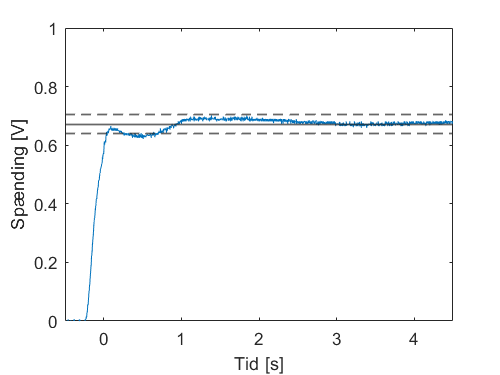

settletime = 0.6975

temp = 0.6975

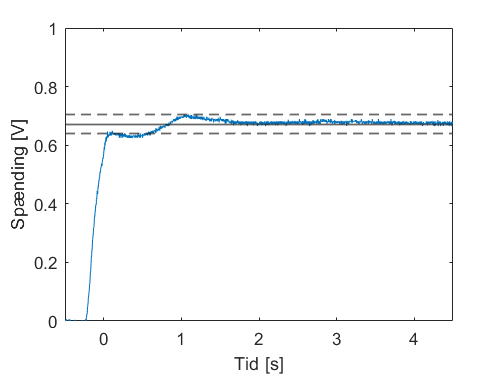

settletime = 0.6000

temp =     0.6975    0.6000


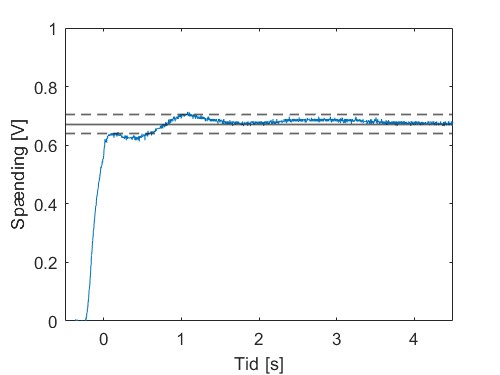

settletime = 1.1175

temp =     0.6975    0.6000    1.1175


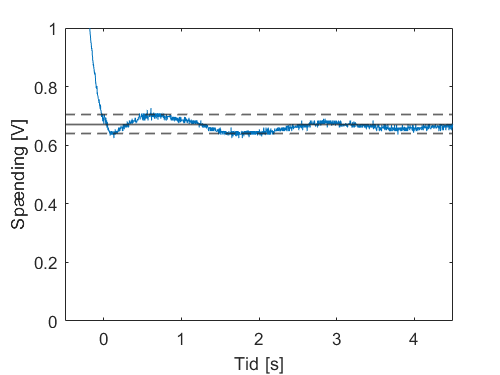

settletime = 3.7900

temp =     0.6975    0.6000    1.1175    3.7900


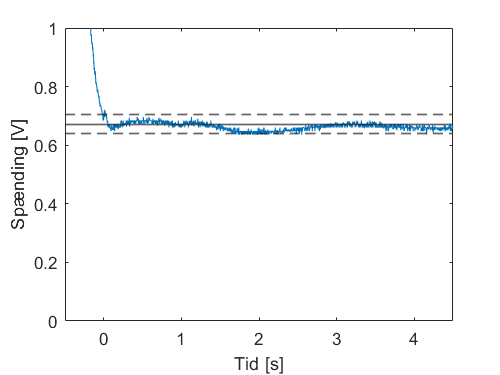

settletime = 4.1600

temp =     0.6975    0.6000    1.1175    3.7900    4.1600


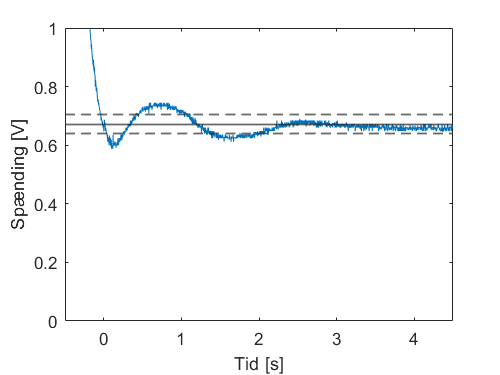

settletime = 2.1200

temp =     0.6975    0.6000    1.1175    3.7900    4.1600    2.1200


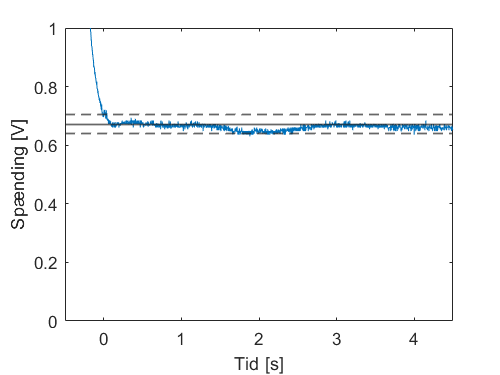

settletime = 4

temp =     0.6975    0.6000    1.1175    3.7900    4.1600    2.1200    4.0000


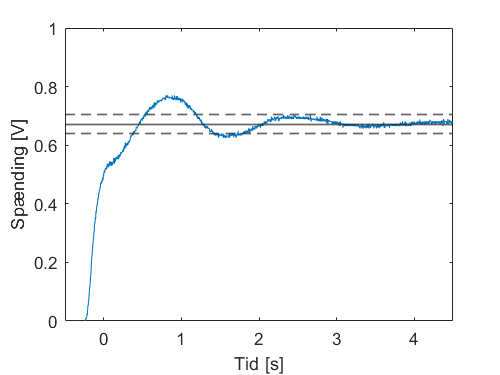

settletime = 1.8125

temp =     0.6975    0.6000    1.1175    3.7900    4.1600    2.1200    4.0000    1.8125


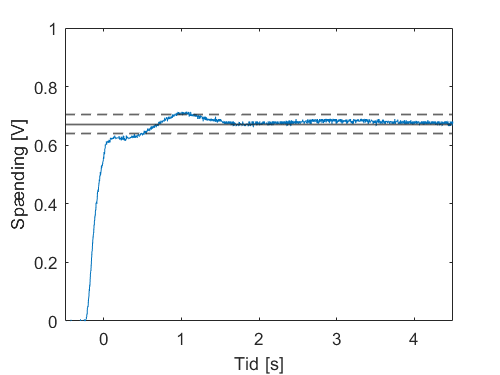

settletime = 1.1725

temp =     0.6975    0.6000    1.1175    3.7900    4.1600    2.1200    4.0000    1.8125    1.1725


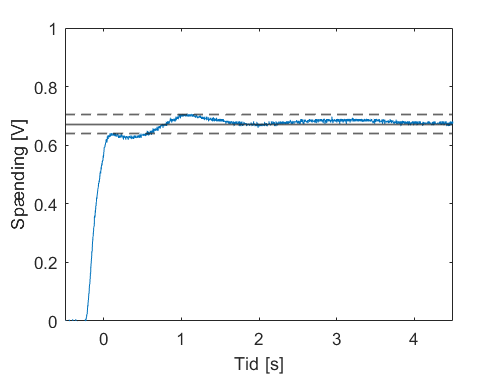

settletime = 1.0675

temp =     0.6975    0.6000    1.1175    3.7900    4.1600    2.1200    4.0000    1.8125    1.1725    1.0675


files = dir('*.csv');
for k = 1:length(files)
    if(files(k).name == "ref.csv")
        refMeas = readmatrix("ref.csv", 'NumHeaderLines',2);
        ref = refMeas(:,2);
        time = refMeas(:,1);
        middle = mean(ref);
        general = [middle, middle + middle*0.05, middle - middle * 0.05];
        elses
        MeasData = readmatrix(files(k).name, NumHeaderLines=2);
        Meas = MeasData(:,2);
        figure(k);
        plotMeas(time, Meas, general)
        saveas(gcf,string(k),'epsc');
        temp(k-1) = settleTime(time, Meas, general)
    end
end

## Funktioner

function plotMeas(t, meas, gen)
    plot(t, meas)
    yline(gen(1),'-', 'linewidth', 1)
    yline(gen(2:3), '--', 'linewidth', 1)
    xlabel('Tid [s]')
    ylabel('Spænding [V]')
    xlim([-.5 4.5])
    ylim([0 1])
end
function [time] = settleTime(t, meas, gen)
    lastVal = max(find( meas>=gen(2) |  meas<=gen(3)));
    settletime = t(lastVal)
    time = settletime;
end